clear all

h = 1;
z0 = [10.0 0.0];
dtlin = zeros(size(1:9));
dxlin = zeros(size(1:9));
for i = 1:9
    h
    dtlin(i) = h;
    dxlin(i) = abs(z0(1)-RK4lin(z0, h));
    h = h/10;
end

h = 1

h = 0.1000

h = 0.0100

h = 1.0000e-03

h = 1.0000e-04

h = 1.0000e-05

h = 1.0000e-06

h = 1.0000e-07

h = 1.0000e-08

save("linear.mat")

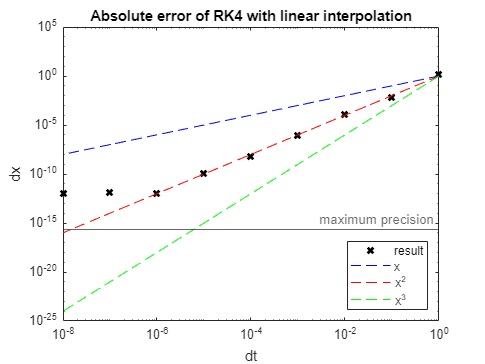

clear all
load("linear.mat")
loglog(dtlin,dxlin,"xblack",'LineWidth',2)
hold on
loglog(dtlin,dtlin,"b--")
loglog(dtlin,dtlin.^2,"r--")
loglog(dtlin,dtlin.^3,"g--")
hold off
xlabel("dt"), ylabel("dx")
legend("result","x","x^2","x^3",'Location',"southeast",'AutoUpdate','off')
title("Absolute error of RK4 with linear interpolation")
yline(2^-52,'-','maximum precision','LabelHorizontalAlignment','right')

function out = odefcn(z)
    out= [z(2), -z(1)];
end

function xzero = RK4lin(z0, h)
    xprev = z0(1);
    yprev = z0(2);
    
    k1 = odefcn([xprev, yprev]);
    k2 = odefcn([xprev + k1(1) * h/2, yprev + k1(2) * h/2]);
    k3 = odefcn([xprev + k2(1) * h/2, yprev + k2(2) * h/2]);
    k4 = odefcn([xprev + k3(1) * h  , yprev + k3(2) * h  ]);
    
    x = xprev + (h/6) * (k1(1) + 2*k2(1) + 2*k3(1) + k4(1));
    y = yprev + (h/6) * (k1(2) + 2*k2(2) + 2*k3(2) + k4(2));
    
    count = 0;
    
    while count < 2
        
        xprev = x;
        yprev = y;
        
        k1 = odefcn([xprev, yprev]);
        k2 = odefcn([xprev + k1(1) * h/2, yprev + k1(2) * h/2]);
        k3 = odefcn([xprev + k2(1) * h/2, yprev + k2(2) * h/2]);
        k4 = odefcn([xprev + k3(1) * h  , yprev + k3(2) * h  ]);
    
        x = xprev + (h/6) * (k1(1) + 2*k2(1) + 2*k3(1) + k4(1));
        y = yprev + (h/6) * (k1(2) + 2*k2(2) + 2*k3(2) + k4(2));
        
        if y*yprev < 0
            count = count+1;
        end
        
    end
    
    xzero = xprev - yprev*(x-xprev)/(y-yprev);
    
end